% Load pre-trained Faster R-CNN model for people detection
detector = peopleDetectorACF;

% Specify binary classification CNN model architecture (customize as needed)
layers = [
    imageInputLayer([300 600 3])
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

% Specify training options
options = trainingOptions('sgdm', 'MaxEpochs', 20, 'MiniBatchSize', 32, 'InitialLearnRate', 1e-3);

binaryLabels = categorical([0,1,1,0,0,1,1,0,1,0,1,1,0,0,0,1,0,1,0,0,0,0,1,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,0,1,1,0,0,1,1,1,0,1,0,1]);
% Train the binary classification model
% Assuming binaryLabels is a vector of binary labels (0 or 1)
data = imageDatastore('Cv_resized_images\', 'Labels', binaryLabels);

binaryClassifier = trainNetwork(data, layers, options);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       46.88% |       0.9299 |          0.0010 |
|      20 |          20 |       00:01:17 |      100.00% |   0.0000e+00 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.



% Test the system on a new image
img = imread('test_image.jpg');
[bboxes, scores] = detect(detector, img);
imshow(img);
prediction = classify(binaryClassifier, img);
disp(prediction);

     1 



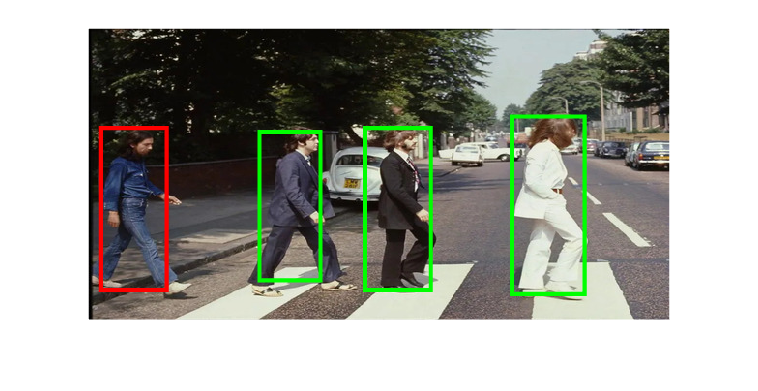

     1 

     0 

     1 

     1 



for i = 1:size(bboxes, 1)
    % Extract and resize the region containing a person
    personImage = imcrop(img, bboxes(i, :));
    personImage = imresize(personImage, [300 600]);

    % Use the binary classifier to determine if the person is on a zebra crossing
    prediction = classify(binaryClassifier, personImage);

    disp(prediction)
    % Display the results
    if prediction == categorical(1)
        % Person is on a zebra crossing
        rectangle('Position', bboxes(i, :), 'EdgeColor', 'g', 'LineWidth', 2);
    else
        % Person is not on a zebra crossing
        rectangle('Position', bboxes(i, :), 'EdgeColor', 'r', 'LineWidth', 2);
    end
end